# Calc rotor and Prop Inertia - **3 bladed propeller **case

The purpose of this report is to calculate the combined INERTIA of the propeller and the rotor of the electric motor

**ATTENTION:  **

We need to calculate this so that we can use this inerti in the models of the electric motor

Consider the schematic below:

    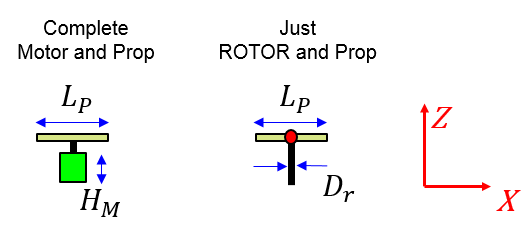     

## Let's define some of the geometry of the system

The ROTOR:

format longG

H_M    = 4/100;   % (m)
H_rot  = 6/100;   % (m)
D_R    = 0.6/100; % (m)
mass_R = 11/1000; % (kg)

The PROPELLERS:

The following properties are from the 3-blade Master Airscrew propeller listed [**HERE**](http://www.masterairscrew.com/collections/3-blade/products/3-blade-6x4-propeller)

prop_diam   = 0.152;       % (m)
blade_len   = prop_diam/2; % (m) 
blade_wid   = 1/100;       % (m) - estimated width of blade
L_P         = prop_diam;   % (m)
D_P         = 3.5/1000;    % (m) - estimated average thickness of blade
mass_P      = 6.8/1000;    % (kg)
mass_Pblade = mass_P/3;    % (kg) - mass of 1 blade of the propeller

## Calculate the system CM relative to RED DOT

prop_loc_CM  = [0, 0, 0 ];
rotor_loc_CM = [0, 0, (-D_P/2 + -H_rot/2)];

total_mass = mass_R + mass_P;
sys_CM_relto_red_dot = (rotor_loc_CM*mass_R  +  ...
                         prop_loc_CM*mass_P ) / total_mass

sys_CM_relto_red_dot =          0         0   -0.0196


                     
% specify the component CMs relative to the system CM
rc_rot  = rotor_loc_CM - sys_CM_relto_red_dot

rc_rot =          0         0   -0.0121


rc_prop = prop_loc_CM  - sys_CM_relto_red_dot

rc_prop =          0         0    0.0196


**Calculate the combined inertia (prop+rotor)**

First the rotor:

rotor       = inertia_cylinder_VERT_CLS(H_rot, D_R/2, mass_R);
I_LOC_rotor = rotor.get_I();
OBJ_R       = inertia_parallel_local_to_desired_CLS(rc_rot, I_LOC_rotor, mass_R);
OBJ_R.calc_I_GLOB()

ans =    1.0e-05 *

    0.4943         0         0
         0    0.4943         0
         0         0    0.0050


Next, the 3-bladed propeller assembly.

- NOTE:  see the following tutorial on the 3 baded propeller `bh_TUT_3blade_propeller`

prop        = inertia_3bladed_trp_propeller_CLS(blade_len, blade_wid, mass_Pblade);
I_LOC_prop  = prop.get_I();
OBJ_P       = inertia_parallel_local_to_desired_CLS(rc_prop, I_LOC_prop, mass_P);
OBJ_P.calc_I_GLOB()

ans =    1.0e-04 *

    0.0919         0         0
         0    0.0919         0
         0         0    0.1315



I_combined = OBJ_R.calc_I_GLOB() + ...
             OBJ_P.calc_I_GLOB()

I_combined =    1.0e-04 *

    0.1414         0         0
         0    0.1414         0
         0         0    0.1320
